# 题目10：拉普拉斯锐化

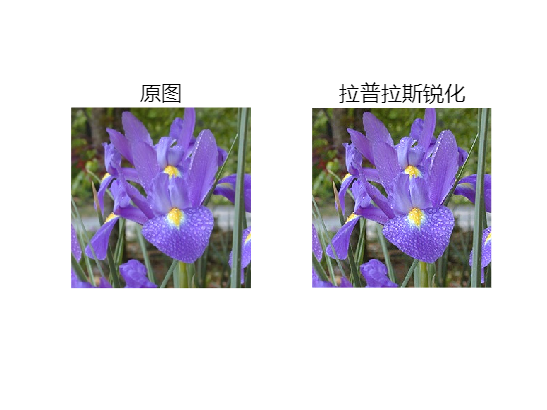

lap_kernel = [0 -1 0; -1 4 -1; 0 -1 0]; % 3×3拉普拉斯算子

% 对每个通道锐化
R_lap = imfilter(img_rgb(:,:,1), lap_kernel, 'replicate');
G_lap = imfilter(img_rgb(:,:,2), lap_kernel, 'replicate');
B_lap = imfilter(img_rgb(:,:,3), lap_kernel, 'replicate');

% 叠加原图
alpha = 0.3;
img_sharp = img_rgb + alpha * cat(3, R_lap, G_lap, B_lap);
img_sharp = max(min(img_sharp, 1), 0);

% 显示结果
figure;
subplot(1,2,1), imshow(img_rgb), title('原图');
subplot(1,2,2), imshow(img_sharp), title('拉普拉斯锐化');